# B.Rain Digital Twin

This is a work done by Michele Simonetti for his master degree thesis in Computer Engineering.

The purpose of this work is to design and develop a digital twin system for the B.Rain device, in order to generate synthetic data which will be adopted to train Machine Learning models for rain intensity prediction.

This repository contains both the Simulink pjoject, composed of the .slx model file, the .m files containing the utility functions and the .mlx Live Script file which can be used to launch the Simulink model, and the Python script for model training and inference.

mdl = 'DigitalTwinMachine';
open_system(mdl)
stopTime = get_param(mdl,'StopTime')

stopTime = '2'

rateDecr = get_param('DigitalTwinMachine/rate_decr','Value')

rateDecr = '0.3'

numGocce = get_param('DigitalTwinMachine/num_gocce','Value')

numGocce = '135'

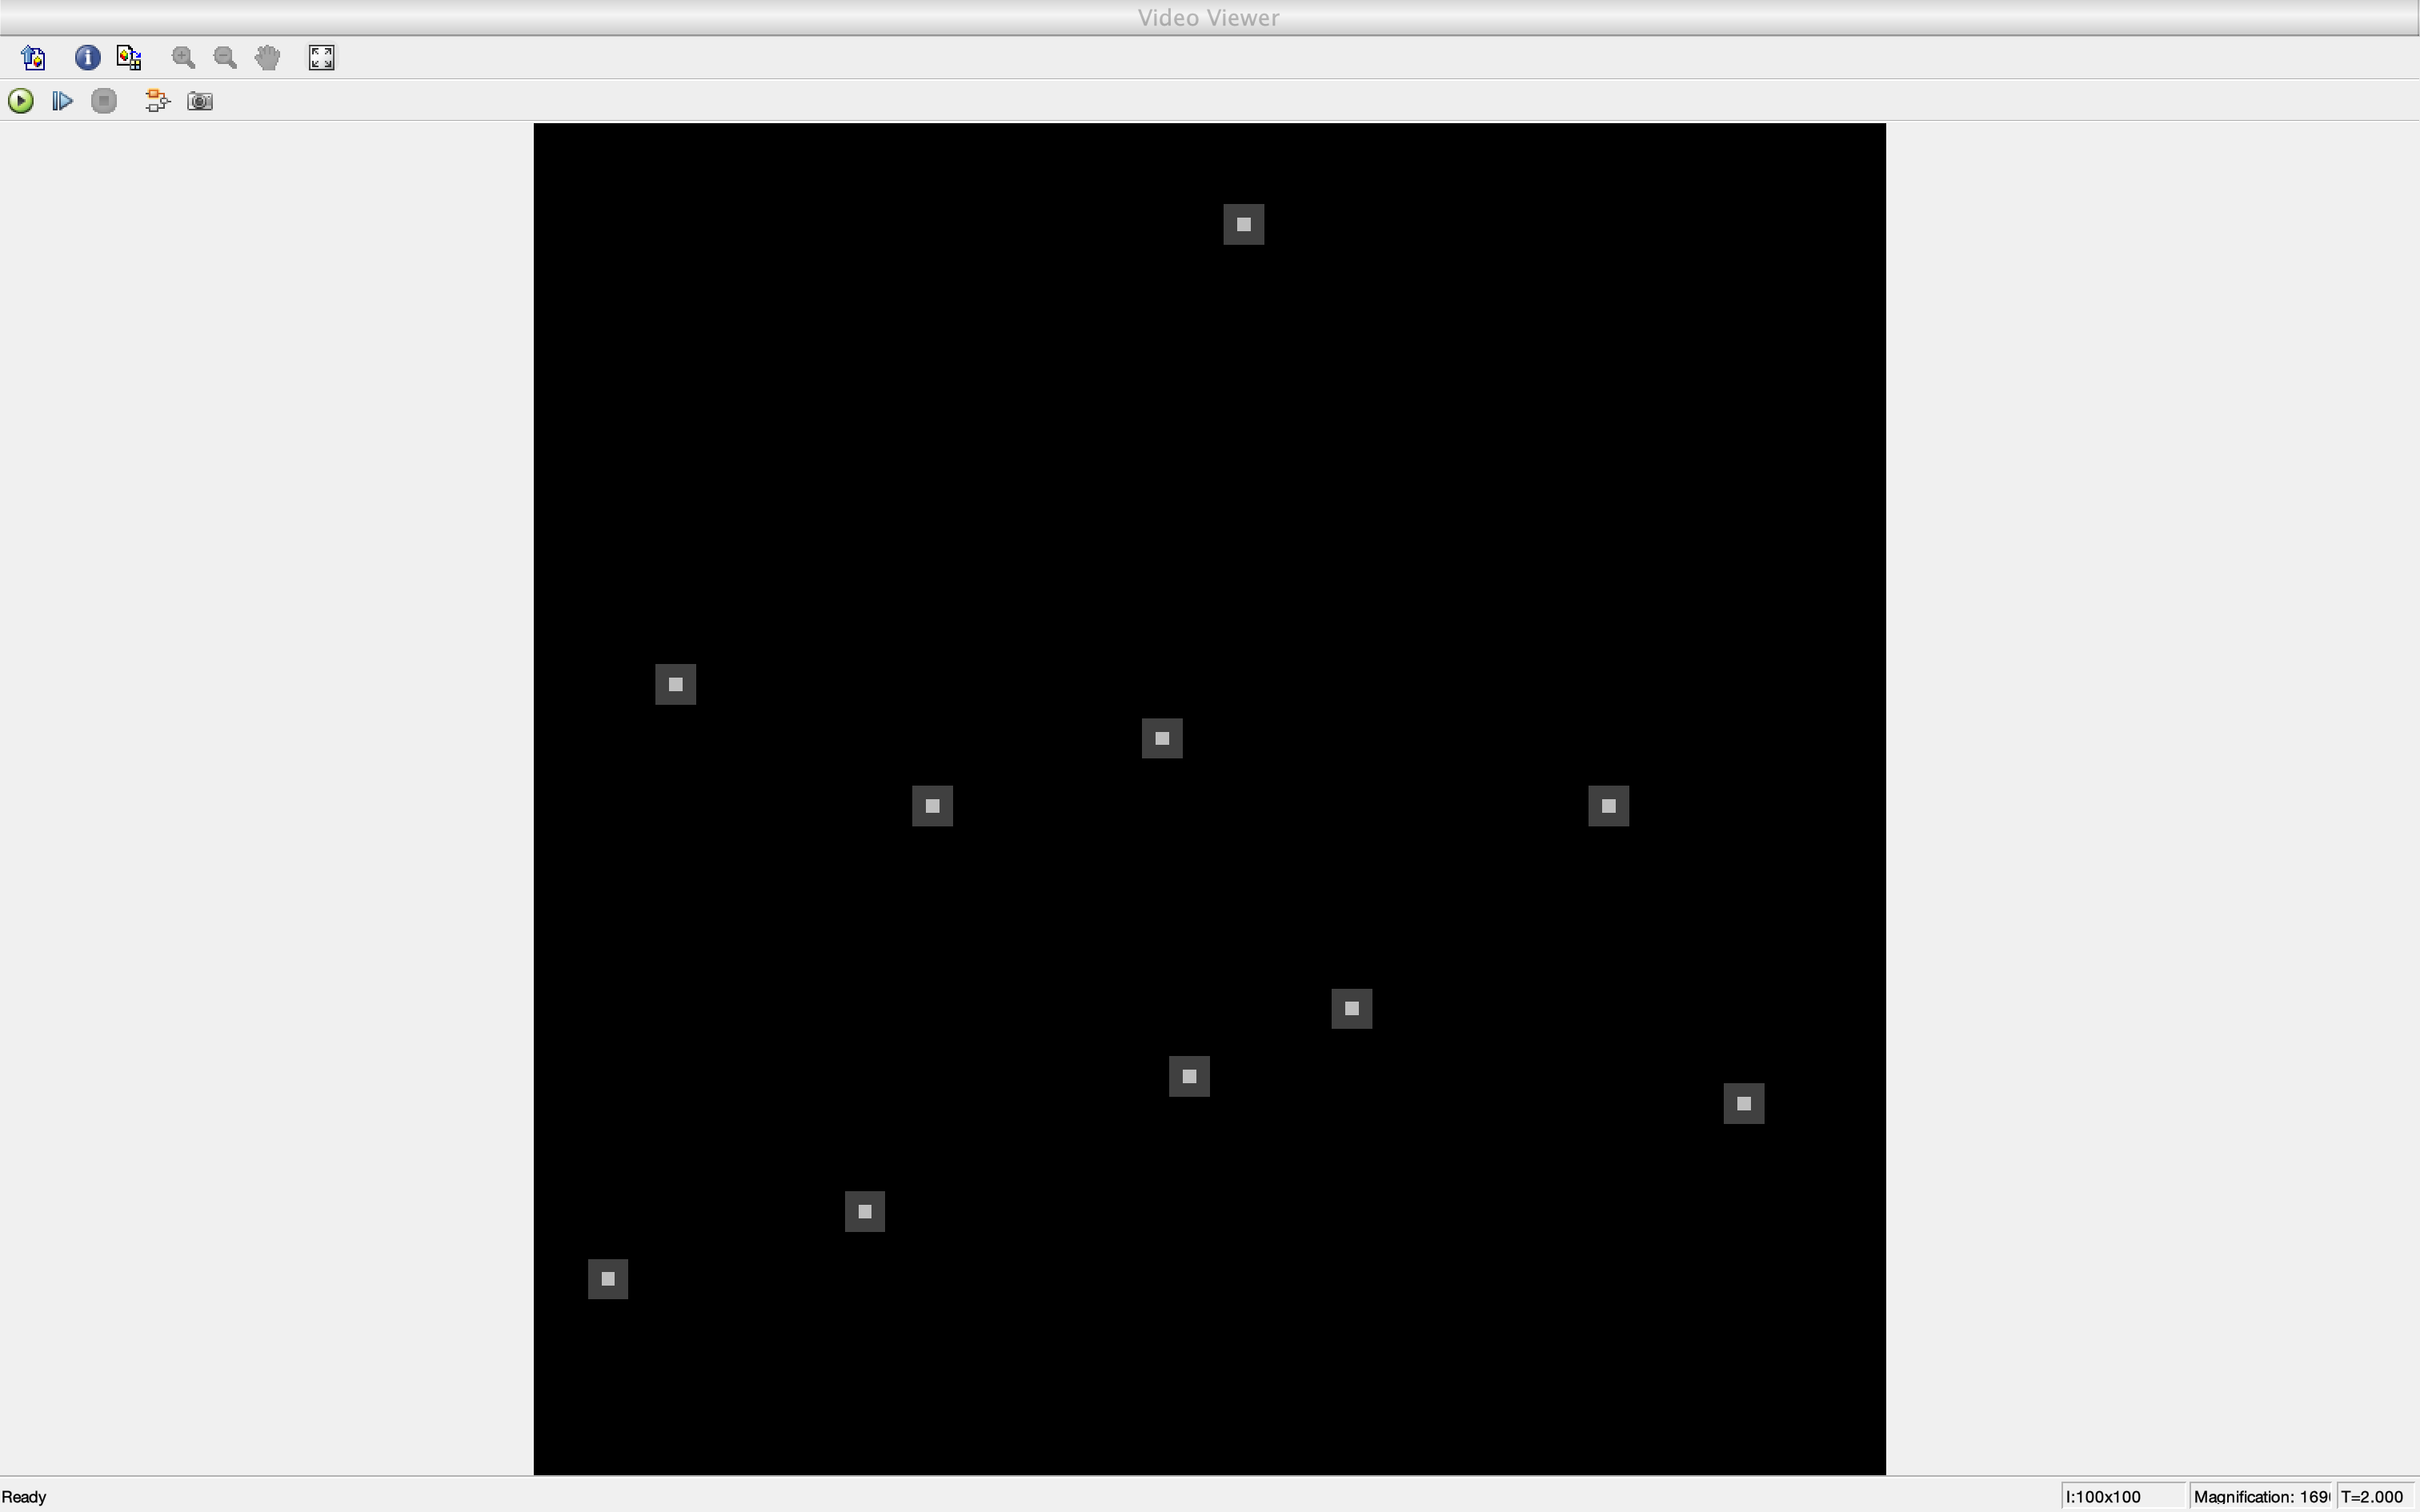

ans =   Simulink.SimulationOutput:

                   tout: [2001x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


sim(mdl)

stopTime = 2;
rateDecr = 0.25;
numGocce = 10;
set_param(mdl,'StopTime',string(stopTime))
set_param('DigitalTwinMachine/rate_decr','Value',string(rateDecr))
set_param('DigitalTwinMachine/num_gocce','Value',string(numGocce))